Model-Free, importance sampling, to reduce the variance using importance sampling - Deepseek-

##  1. Problem Setup (DeepSeek)

We’ll consider a **linear system** with:

- States $x\in R^{2\;}$,

- Control inputs $u\in R^{2\;}$

- The **behavior policy** $u\left(a\left|s\right.\right)\;$is a random policy,

- The **target policy** $\pi \;\left(a\left|s\right.\right)$is a deterministic policy learned by the Actor.

The goal is to learn the optimal policy π(a∣s)\pi(a|s)π(a∣s) and value function V(x) using **real-time Actor-Critic** with **importance sampling**.

**Step 1: Define System and Parameters**

% True system parameters (unknown to the algorithm)
A = [0 1; -1 -0.5]; % True system matrix A (unknown to the algorithm)
B = [0 0; 1 1];     % True input matrix B (unknown to the algorithm)

% Cost function matrices
Q = eye(2);         % State weighting matrix
R = eye(2);         % Control weighting matrix

% Time step for real-time operation
dt = 0.01;          % Time step size

% Simulation time
tspan = 0:dt:10;    % Simulation time span

% Initial state
x0 = [1; 0];        % Initial state vector

**Step 2: Define the System Dynamics**

% System dynamics (unknown to the algorithm)
sys_dynamics = @(t, x, u) A * x + B * u;

**Step 3: Define the Cost Function**

% Cost function
cost_function = @(x, u) x' * Q * x + u' * R * u;

**Step 4: Initialize Actor and Critic Parameters**

% Initial control policy (Actor)
K = zeros(2, 2);    % Initial control gain matrix (2 inputs, 2 states)

% Initial value function parameters (Critic)
P = zeros(2, 2);    % Initial value function matrix

% Actor-Critic parameters
% alpha_actor = 0.01; % Learning rate for Actor
% alpha_critic = 0.01; % Learning rate for Critic
alpha_actor = 0.001; % Learning rate for Actor
alpha_critic = 0.001; % Learning rate for Critic

gamma = 0.99;       % Discount factor
% exploration_noise = 0.1; % Exploration noise (e.g., Gaussian noise)
exploration_noise = 0.01; % Exploration noise (e.g., Gaussian noise)

**Step 5: Define the Policies**

% Behavior policy: random policy (Gaussian noise)
mu = @(x) -K * x + exploration_noise * randn(2, 1);

% Target policy: deterministic policy (Actor)
pi = @(x) -K * x;

**Step 6: Define the Importance Sampling Ratio**

% Importance sampling ratio
% Importance sampling ratio for Gaussian policies
importance_sampling_ratio = @(x, u) exp(-0.5 * (u - pi(x))' * (u - pi(x)) / exploration_noise^2) / ...
                                exp(-0.5 * (u - mu(x))' * (u - mu(x)) / exploration_noise^2);


% importance_sampling_ratio = @(x, u) pi(x) / mu(x); % pi(a|s) / mu(a|s)

**Step 7: Real-Time Actor-Critic with Importance Sampling**

% Initialize state and time
x = x0;             % Initial state
x_history = zeros(2, length(tspan)); % To store state history
u_history = zeros(2, length(tspan)); % To store control history (2 inputs)

% Main real-time Actor-Critic loop
for t = 1:length(tspan)
    % Choose an action using the behavior policy
    u = mu(x);
    u_history(:, t) = u; % Store the control input (vector)
    
    % Simulate the system for one time step
    x_dot = sys_dynamics(tspan(t), x, u);
    x_next = x + x_dot * dt;
    
    % Compute the reward
    r = cost_function(x, u);
    
    % Compute the importance sampling ratio
    rho = importance_sampling_ratio(x, u);
    
    % Critic Update: Estimate the value function
    delta = r + gamma * x_next' * P * x_next - x' * P * x;
    P = P + alpha_critic * rho * delta * (x * x');
    
    % Actor Update: Improve the control policy
    K = K - alpha_actor * rho * delta * (x * u');
    
    % Update the state
    x = x_next;
    x_history(:, t) = x;
end

**Step 8: Plot the Results**

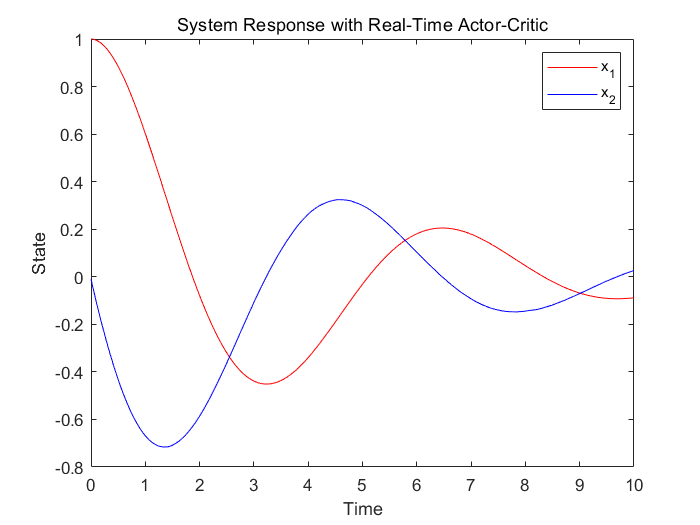

% Plot the system response
figure;
plot(tspan, x_history(1, :), 'r', tspan, x_history(2, :), 'b');
xlabel('Time');
ylabel('State');
legend('x_1', 'x_2');
title('System Response with Real-Time Actor-Critic');

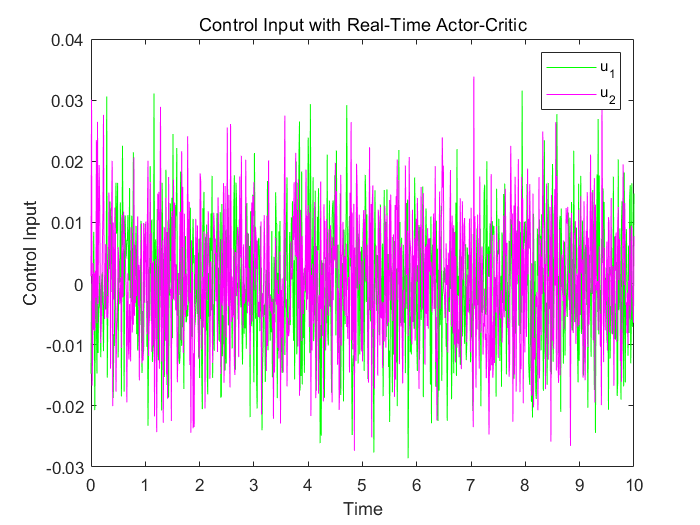


% Plot the control input
figure;
plot(tspan, u_history(1, :), 'g', tspan, u_history(2, :), 'm');
xlabel('Time');
ylabel('Control Input');
legend('u_1', 'u_2');
title('Control Input with Real-Time Actor-Critic');

This MATLAB example demonstrates how to use **importance sampling** in **real-time Actor-Critic** for **off-policy learning**. The importance sampling ratio $\rho \;$ ensures that the updates are more representative of the target policy, leading to more accurate value function and policy estimates.

## 2. Problem Setup (Gemini)

Step 1.LQR Problem Definition (same as before)

%% 1. LQR Problem Definition (same as before)
A = [0 1; 0 0];  % Example: Double integrator
B = [0; 1];
Q = [1 0; 0 1];
R = 1;

% 2. Actor Initialization
K = randn(1, 2);  % Initial random gain matrix (1x2 for scalar input)
learning_rate_actor = 0.01;

% 3. Critic Initialization
P = eye(2);      % Initial estimate of P (2x2)
learning_rate_critic = 0.1;

% 4. Simulation Parameters
num_episodes = 100;
episode_length = 100;
x0 = [1; 0];      % Initial state

% 5. Behavior Policy (Different from target policy)
exploration_noise = 0.5; % Standard deviation of noise added to action

% 6. Main Loop
for episode = 1:num_episodes
  x = x0;

  for t = 1:episode_length
    % Actor: Choose action (Target Policy)
    u_target = -K * x;

    % Behavior Policy: Add noise for exploration
    u = u_target + exploration_noise * randn();  % Add Gaussian noise

    % Simulate system (assuming discrete time)
    x_next = A * x + B * u;  % Simplified discrete-time update
    reward = -(x' * Q * x + u' * R * u);  % Negative cost

    % Critic: Estimate value function
    V = x' * P * x;
    V_next = x_next' * P * x_next;

    % Critic: Calculate TD error
    TD_error = reward + V_next - V;

    % Critic: Update P (simplified update rule)
    P = P + learning_rate_critic * TD_error * (x * x');  % Approximate gradient

    % Importance Sampling: Calculate importance weight
    % Assuming both target and behavior policies are Gaussian
    % with the same variance (exploration_noise^2)
    log_pi_target = -0.5 * ((u - u_target)^2) / (exploration_noise^2);  % log probability under target policy
    log_pi_behavior = -0.5 * ((u - u_target - exploration_noise * randn())^2) / (exploration_noise^2);  % log probability under behavior policy

    importance_weight = exp(log_pi_target - log_pi_behavior);  % exp of log difference

    % Actor: Update K (simplified policy gradient with importance sampling)
    K = K + learning_rate_actor * importance_weight * TD_error * (u * x');  % Approximate gradient

    % Update state
    x = x_next;
  end
end

% Display learned K and P
disp('Learned K:');
disp(K);
disp('Learned P:');
disp(P);

% (Optional) Compare with analytical LQR solution (using lqr() function)
[K_lqr, P_lqr] = lqr(A, B, Q, R);
disp('Analytical LQR K:');
disp(K_lqr);
disp('Analytical LQR P:');
disp(P_lqr);